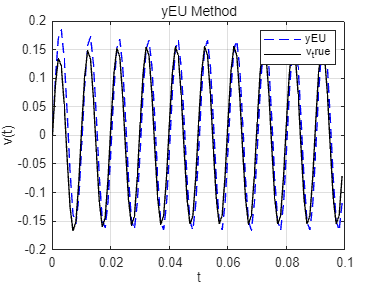

clear all, close all; clc ;

figure, clf, box on, grid on, hold on

a=0; b=0.1; 
h=0.001; 
t=a:h:b-h; 

tau=0.01; f=100; Vm=1; w=2*pi*f;

A=Vm/(sqrt(1+(w*tau)^2));
alpha=-atan(w*tau);

v_true=A*(-cos(alpha)*exp(-t/tau)+cos(w*t+alpha));





% yEU

data1 = readmatrix('yEU.txt');
datat1 = data1';

plot(t, datat1, '--b');
plot(t, v_true, 'k');

legend('yEU','v_true');
title('yEU Method');  

xlabel('t'); 
ylabel('v(t)');

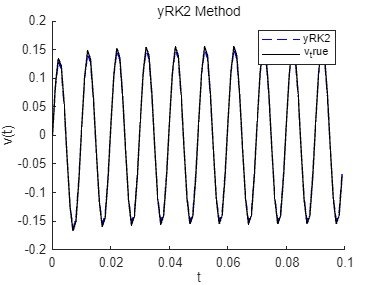


% yRK2

data2 = readmatrix('yRK2.txt');
datat2 = data2';

figure(); hold on
plot(t,datat2,'--b',t,v_true,'k');
legend('yRK2','v_true');
title('yRK2 Method');  

xlabel('t'); 
ylabel('v(t)');

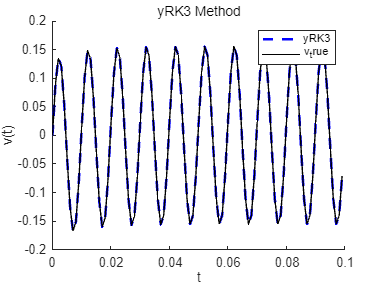


% yRK3

data3 = readmatrix('yRK3.txt');
datat3 = data3';

figure(); hold on
plot(t, datat3, '--b', 'LineWidth', 2);
plot(t, v_true, 'k');

legend('yRK3','v_true');
title('yRK3 Method');  

xlabel('t'); 
ylabel('v(t)');

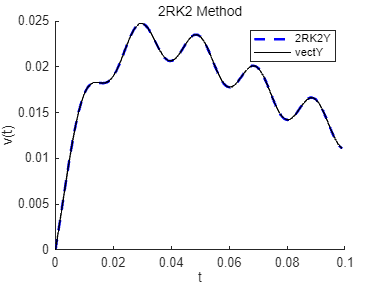



% ------------------------------------------------- 

a2=0;
b2=1-0.01;
h2=0.01;
N2 = (b-a)/h2;

yINI = 0;
vINI = 0.2;

[tref, vecY] = ode45(@odeFunc_mck, [a2:h2:b2], [yINI, vINI]);



% 2RK2_Y

data4 = readmatrix('2RK2_Y.txt');
datat4 = data4';

figure(); hold on
plot(t, datat4, '--b', 'LineWidth', 2);
plot(t, vecY(:,1), 'k');

legend('2RK2Y','vectY');
title('2RK2 Method');  

xlabel('t'); 
ylabel('v(t)');

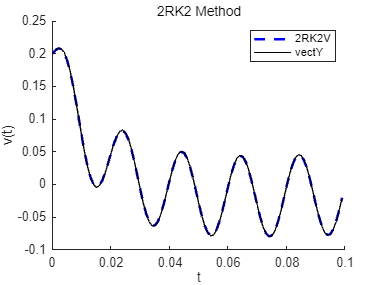



% 2RK2_Y

data5 = readmatrix('2RK2_V.txt');
datat5 = data5';

figure(); hold on
plot(t, datat5, '--b', 'LineWidth', 2);
plot(t, vecY(:,2), 'k');

legend('2RK2V','vectY');
title('2RK2 Method');  

xlabel('t'); 
ylabel('v(t)');

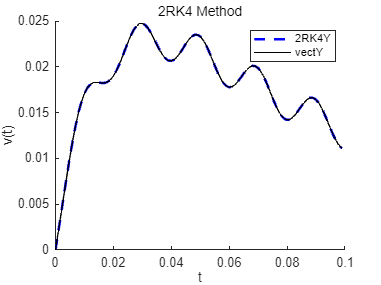



% 2RK4_Y

data6 = readmatrix('2RK4_Y.txt');
datat6 = data6';

figure(); hold on
plot(t, datat6, '--b', 'LineWidth', 2) ;
plot(t, vecY(:,1), 'k') ;

legend('2RK4Y','vectY') ; 
title('2RK4 Method') ;  

xlabel('t'); 
ylabel('v(t)');

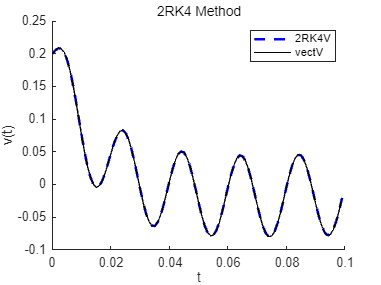


% 2RK4_V

data7 = readmatrix('2RK4_V.txt');
datat7 = data7';

figure(); hold on
plot(t, datat7, '--b', 'LineWidth', 2) ;
plot(t, vecY(:,2), 'k') ;

legend('2RK4V','vectV') ; 
title('2RK4 Method') ;  

xlabel('t'); 
ylabel('v(t)');




% 함수 선언 %

function [dYdt] = odeFunc_mck(t,vecY)

    dYdt=zeros(2,1);    
    
    % System Modeling parameters 
    m=1; k=6.9; c=10*0.7;
    FinDC=2;    f=5;
    Fin=FinDC*cos(2*pi*f*t);
    
    % Output    
    dYdt(1)=vecY(2); 
    dYdt(2)=1/m*(Fin-c*vecY(2)-k*vecY(1));

end 
